# Actividad 5: Robot 3GDL

**Paola Rojas Domínguez A01737136**

Este robot de 3 grados de libertad (GDL) es un tipo de manipulador cuya estructura se basa en movimientos de traslación lineales y, en algunos casos, rotaciones simples.

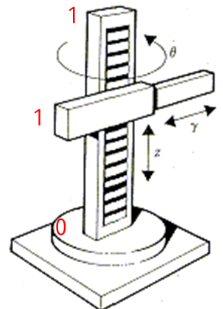

## Inicialización y Declaración de Variables

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

Posteriormente, se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

syms t th1(t) l2(t) l3(t) l1

Se configura el robot con una articulacion rotacional y dos prissmáticas, representando su tipo con un vector donde 0 es rotacional y 1 prismático

RP=[0 1 1];

Creamos el vector de coordenadas generalizadas

Q= [th1, l2, l3];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
(th1(t), l2(t), l3(t))



Creamos el vector de velocidades generalizadas.

Qp= diff(Q, t);
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
/  d          d         d       \
| -- th1(t), -- l2(t), -- l3(t) |
\ dt         dt        dt       /



Posteriormente, definimos los grados de libertad (GDL), es decir, el número de parámetros independientes que definen la posición del extremo del robot, en este caso 4 GDL.

GDL= size(RP,2);
GDL_str= num2str(GDL);

## Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

### Articulación 1

La primera articulación (a diferencia de las otras 2), es rotacional. Aquí, el sistema de coordenadas 2 se obtiene girando el sistema de coordenadas 1 en el eje y 90 positivos.


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$R_y \left(90\right)\left\lbrack \begin{array}{ccc}
\cos \left(90\right) & 0 & \textrm{sen}\left(90\right)\\
0 & 1 & 0\\
-\textrm{sen}\left(90\right) & 0 & \cos \left(90\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times \left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \sin \left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$$


%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;l1];

%Matriz de rotación de la junta 1 a 2
R(:,:,1)= [0 -sin(th1)  cos(th1) ;
           0  cos(th1)  sin(th1) ;
          -1  0         0];

### Articulación 2

Se aplica una rotación negativa de 90° alrededor del eje y. Aquí, el sistema de coordenadas 3 se obtiene girando el sistema de coordenadas 2 en el eje y.


$$R_y \left(-90\right)\left\lbrack \begin{array}{ccc}
\cos \left(-90\right) & 0 & \mathrm{sen}\left(-90\right)\\
0 & 1 & 0\\
-\mathrm{sen}\left(-90\right) & 0 & \cos \left(-90\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$$


%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [0; 0; l2];

%Matriz de rotación de la junta 2 a 3
R(:,:,2)= [0  0 -1;
           0  1  0;
           1  0  0];

### Articulación 3 

Para este caso utilizamos la matriz identidad, esto debido a que no hay transformación adicional entre estos sistemas de referencia, lo que significa que los ejes quedan alineados sin modificaciones en posición u orientación.

%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0; l3];

%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)=   [1  0  0;
             0  1  0;
             0  0  1];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano.

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty (A(:,:,i));
    disp('    ');

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i));
    disp('    ');

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/  0, -sin(th1(t)), cos(th1(t)),  0 \
|                                   |
|  0,  cos(th1(t)), sin(th1(t)),  0 |
|                                   |
| -1,       0,           0,      l1 |
|                                   |
\  0,       0,           0,       1 /



Matriz de Transformación global T1
/  0, -sin(th1(t)), cos(th1(t)),  0 \
|                                   |
|  0,  cos(th1(t)), sin(th1(t)),  0 |
|                                   |
| -1,       0,           0,      l1 |
|                                   |
\  0,       0,           0,       1 /



Matriz de Transformación local A2
/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l2(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T2
/ cos(th1(t)), -sin(th1(t)), 0, cos(th1(t)) l2(t) \
|                                                 |
| sin(th1(t)),  cos(th1(t)), 0, sin(th1(t)) l2(t) |
|                                                 |
|      0,            0,      1,         l1        |
|                                                 |
\      0,            0,      0,         1         /



Matriz de Transformación local A3
/ 1, 0, 0,   0   \
|                |
| 0, 1, 0,   0   |
|                |
| 0, 0, 1, l3(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T3
/ cos(th1(t)), -sin(th1(t)), 0, cos(th1(t)) l2(t) \
|                                                 |
| sin(th1(t)),  cos(th1(t)), 0, sin(th1(t)) l2(t) |
|                                                 |
|      0,            0,      1,     l1 + l3(t)    |
|                                                 |
\      0,            0,      0,         1         /



## Cálculo del jacobiano lineal de forma diferencial

El Jacobiano es una matriz que relaciona las velocidades articulares con las velocidades lineales y angulares del extremo del robot. El Jacobiano lineal (Jv), relaciona velocidades articulares con velocidad lineal del extremo. Mientras que el Jacobiano angular (Jw), relaciona velocidades articulares con velocidad angular.

El Jacobiano diferencial es obtenido mediante derivadas parciales de la posición.

%Derivadas parciales de x respecto a l1, l2 y l3
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);

%Derivadas parciales de y respecto a l1, l2 y l3
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);

%Derivadas parciales de z respecto a l1, l2 y l3
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
               Jv21 Jv22 Jv23;
               Jv31 Jv32 Jv33]);

disp('Jacobiano lineal obtenido de forma diferencial'); pretty(jv_d);

Jacobiano lineal obtenido de forma diferencial
/ -sin(th1(t)) l2(t), cos(th1(t)), 0 \
|                                    |
|  cos(th1(t)) l2(t), sin(th1(t)), 0 |
|                                    |
\          0,              0,      1 /



## Cálculo del jacobiano lineal y angular de forma analítica

El jacobiano analítico es calculado mediante productos vectoriales, considerando el tipo de articulación

%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
        end

     elseif RP(k)==1 %Casos: articulación prismática
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Despliegue
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty (Jv_a);

Jacobiano lineal obtenido de forma analítica
/ -sin(th1(t)) l2(t), cos(th1(t)), 0 \
|                                    |
|  cos(th1(t)) l2(t), sin(th1(t)), 0 |
|                                    |
\          0,              0,      1 /



disp('Jacobiano ángular obtenido de forma analítica'); pretty (Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 0, 0 /



## Velocidades Lineales y Angulares

Finalmente, se obtienen las velocidades multiplicando los jacobianos por el vector de velocidades articulares

La velocidad lineal describe el desplazamiento del efector.

V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/ ________               _________                   \
|  d                      d                          |
| -- l2(t) cos(th1(t)) - -- th1(t) sin(th1(t)) l2(t) |
| dt                     dt                          |
|                                                    |
| ________               _________                   |
|  d                      d                          |
| -- l2(t) sin(th1(t)) + -- th1(t) cos(th1(t)) l2(t) |
| dt                     dt                          |
|                                                    |
|                      ________                      |
|                       d                            |
|                      -- l3(t)                      |
\                      dt                            /



Mientras que la velocidad angular describe la rotación del efector.

W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



Este reporte ofrece un análisis teórico y práctico del código MATLAB para comprender la cinemática de un robot cartesiano de 3 GDL, útil para simulaciones y aplicaciones en robótica.